# Plot M3C Variables

buffer

buffer = struct with fields:
              Ts: 1.0000e-04
              is: [9×2000 double]
             ixy: [6×2000 double]
              iB: [9×2000 double]
              iz: [9×2000 double]
              ie: [4×2000 double]
              vs: [9×2000 double]
             vxy: [6×2000 double]
              vB: [9×2000 double]
              vo: [0 0.0272 0.1363 0.3056 0.4891 0.6542 0.7861 0.8821 0.9465 0.9860 1.0084 1.0202 1.0268 1.0318 1.0373 1.0439 1.0514 1.0589 1.0654 1.0697 1.0708 1.0683 1.0621 1.0525 1.0403 1.0263 1.0115 0.9969 0.9828 0.9692 0.9555 … ] (1×2000 double)
              Ec: [9×2000 double]
              vc: [9×2000 double]
         Ec_mean: [202500 2.0250e+05 2.0250e+05 2.0251e+05 2.0252e+05 2.0252e+05 2.0253e+05 2.0254e+05 2.0255e+05 2.0256e+05 2.0256e+05 2.0257e+05 2.0258e+05 2.0259e+05 2.0260e+05 2.0261e+05 2.0261e+05 2.0262e+05 2.0263e+05 2.0264e+05 … ] (1×2000 double)
    Ec_mean_filt: [2.0250e+05 2.0250e+05 2.0250e+05 2.0250e+05 2.0250e+05 2.0250e+05 2.0250e+05 

clf

## is

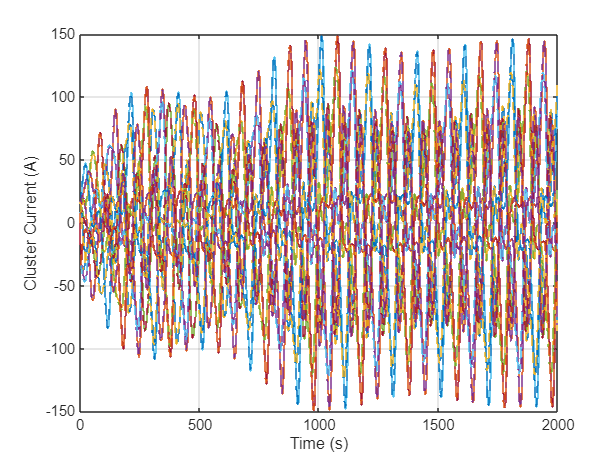

figure
stairs(buffer.is')
hold on
stairs(buffer.is_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Cluster Current (A)')
grid on

## ixy

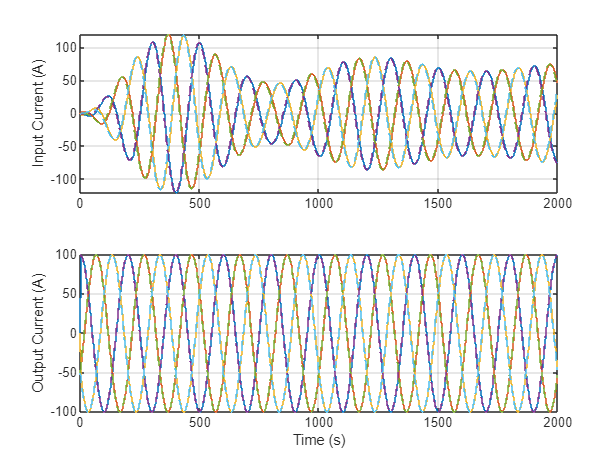

figure
subplot(2, 1, 1)
stairs(buffer.ixy(1:3, :)')
hold on
stairs(buffer.ixy_ref(1:3, :)', '--')
hold off

ylabel('Input Current (A)')
grid on

subplot(2, 1, 2)
stairs(buffer.ixy(4:6, :)')
hold on
stairs(buffer.ixy_ref(4:6, :)', '--')
hold off

xlabel('Time (s)')
ylabel('Output Current (A)')
grid on

## `iB`

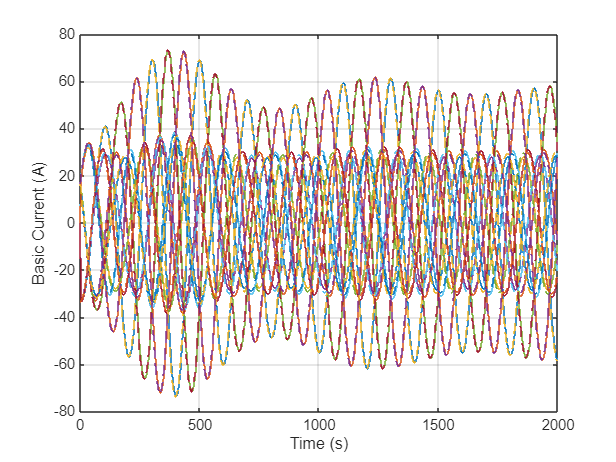

figure
stairs(buffer.iB')
hold on
stairs(buffer.iB_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Basic Current (A)')
grid on

## `iz`

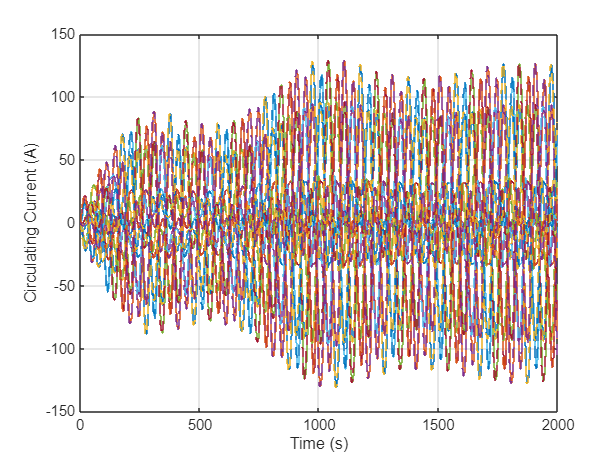

figure
stairs(buffer.iz')
hold on
stairs(buffer.iz_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Circulating Current (A)')
grid on

## `ie`

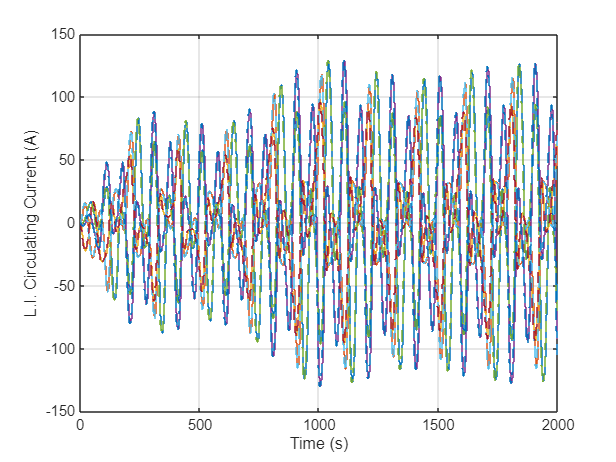

figure
stairs(buffer.ie')
hold on
stairs(buffer.ie_ref', '--')
hold off
xlabel('Time (s)')
ylabel('L.I. Circulating Current (A)')
grid on

## `vs`

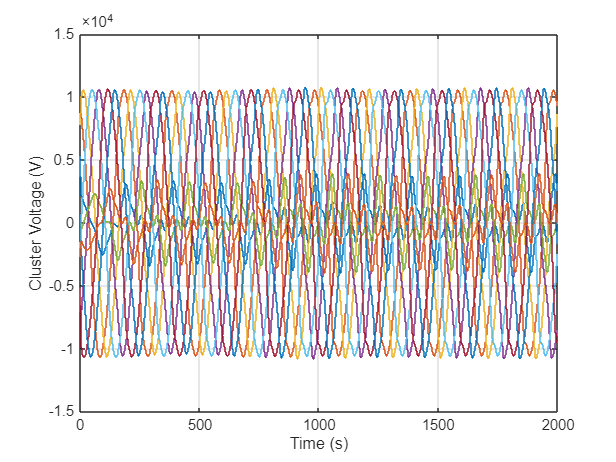

figure
stairs(buffer.vs')
xlabel('Time (s)')
ylabel('Cluster Voltage (V)')
grid on

## `vxy`

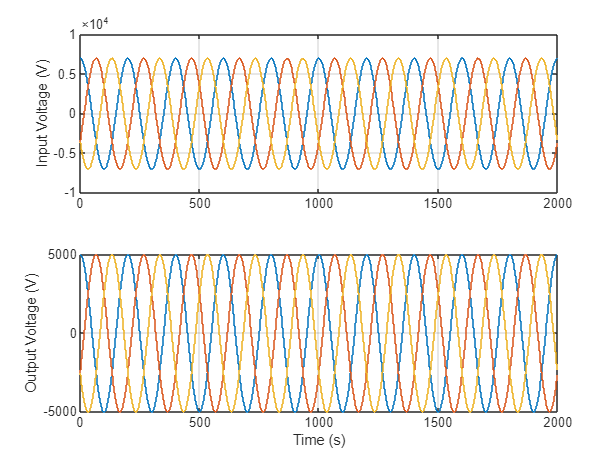

figure
subplot(2, 1, 1)
stairs(buffer.vxy(1:3, :)')

ylabel('Input Voltage (V)')
grid on

subplot(2, 1, 2)
stairs(buffer.vxy(4:6, :)')

xlabel('Time (s)')
ylabel('Output Voltage (V)')
grid on

## `vB`

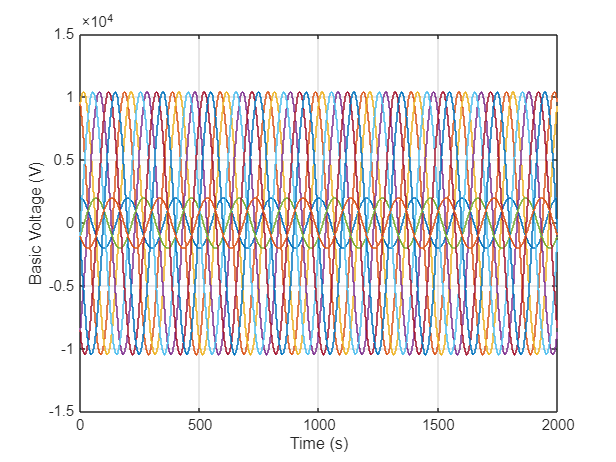

figure
stairs(buffer.vB')
xlabel('Time (s)')
ylabel('Basic Voltage (V)')
grid on

## `vo`

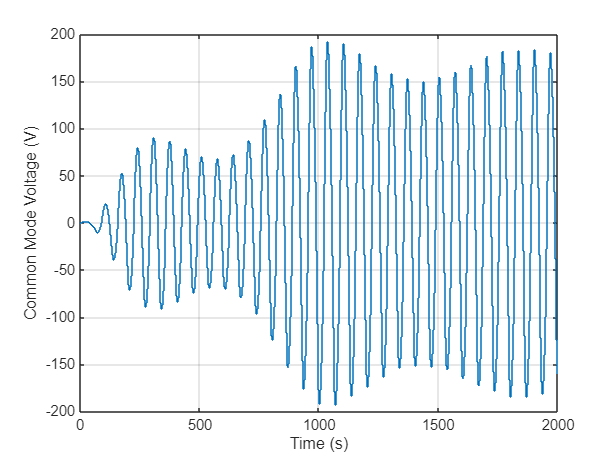

figure
stairs(buffer.vo')
xlabel('Time (s)')
ylabel('Common Mode Voltage (V)')
grid on

## `Ec`

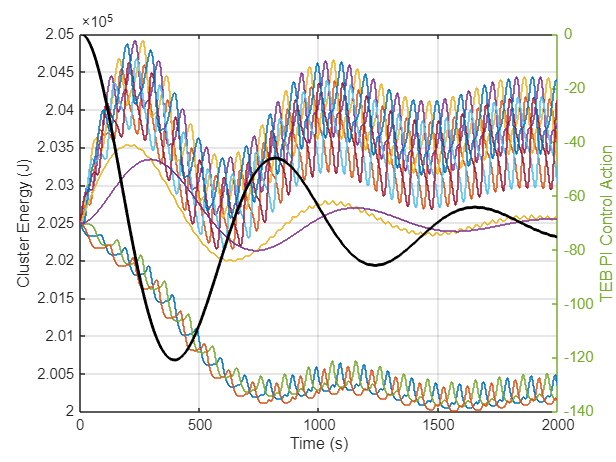

figure
stairs(buffer.Ec')
hold on
stairs(buffer.Ec_mean')
stairs(buffer.Ec_mean_filt')
hold off
ylabel('Cluster Energy (J)')
xlabel('Time (s)')
grid on

## `vc`

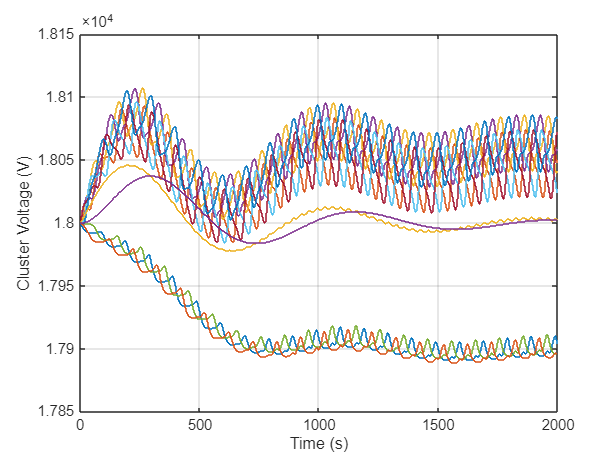

figure

stairs(buffer.vc')
hold on
stairs(buffer.vc_mean')
stairs(buffer.vc_mean_filt')
hold off
ylabel('Cluster Voltage (V)')

yyaxis right
stairs(buffer.u_TEB', 'LineWidth', 2, 'Color', 'black')
ylabel('TEB PI Control Action')

xlabel('Time (s)')
grid on

## Input PLL

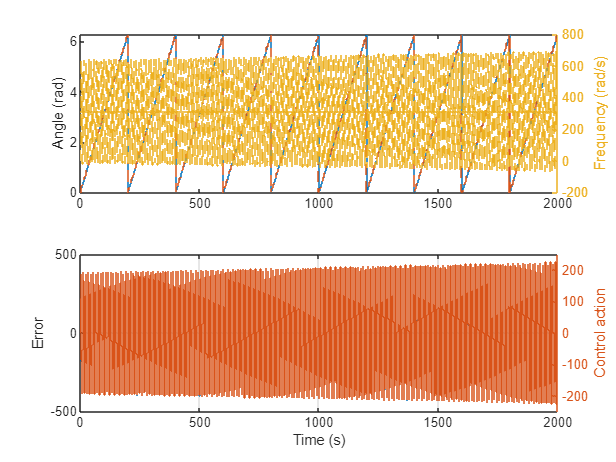

figure

% Estimations
subplot(2, 1, 1)

% Angle
stairs(buffer.gx')
hold on
stairs(buffer.gx_pll', '--')
hold off
ylabel('Angle (rad)')

% Frequency
yyaxis right
stairs(buffer.wx')
hold on
stairs(buffer.wx_pll', '--')
hold off
ylabel('Frequency (rad/s)')

% Performance
subplot(2, 1, 2)

% Error
stairs(buffer.ex_pll')
ylabel('Error')

% Control action
yyaxis right
stairs(buffer.ux_pll')
ylabel('Control action')

xlabel('Time (s)')
grid on

## Output PLL

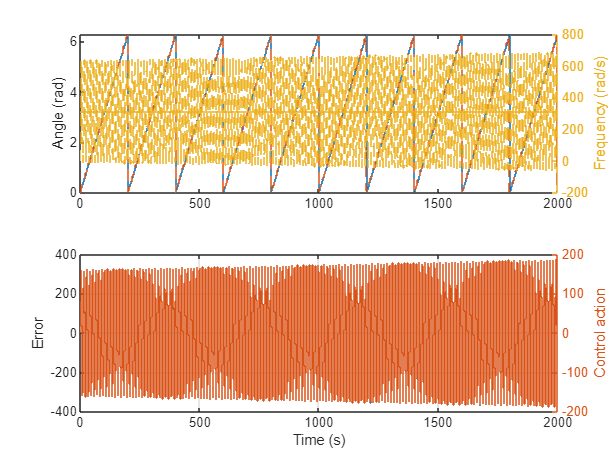

figure

% Estimations
subplot(2, 1, 1)

% Angle
stairs(buffer.gy')
hold on
stairs(buffer.gy_pll', '--')
hold off
ylabel('Angle (rad)')

% Frequency
yyaxis right
stairs(buffer.wy')
hold on
stairs(buffer.wy_pll', '--')
hold off
ylabel('Frequency (rad/s)')

% Performance
subplot(2, 1, 2)

% Error
stairs(buffer.ey_pll')
ylabel('Error')

% Control action
yyaxis right
stairs(buffer.uy_pll')
ylabel('Control action')

xlabel('Time (s)')
grid on